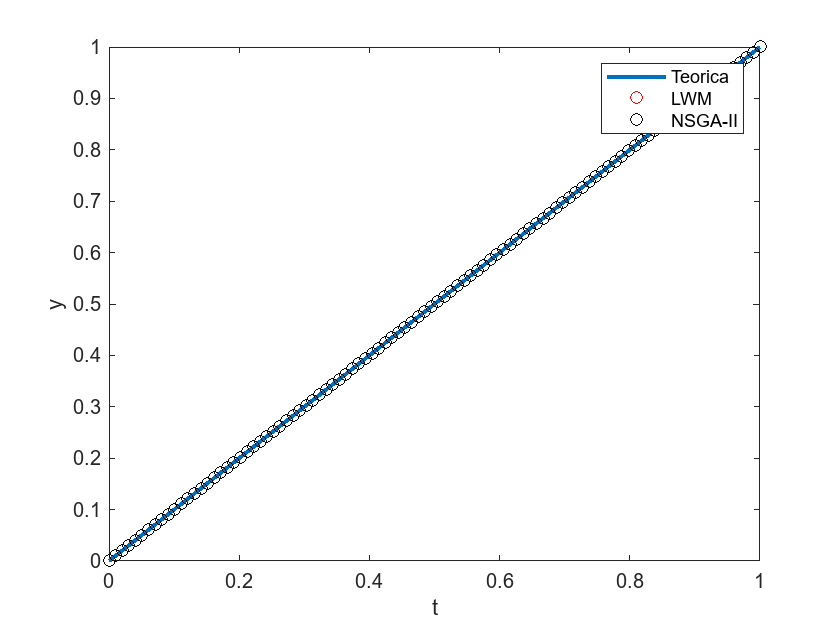

clear
syms A00 A01 t
assume(t,'real');
assume(A00,'real');
assume(A01,'real');

phi00 = @(t) 1;
phi01 = @(t) sqrt(3)*(2*t-1);
A = [A00
     A01];
phit = @(t) [phi00(t)
    phi01(t)];
y = @(t) A'*phit(t);
D = [0 0
    2*sqrt(3) 0];
yp = @(t) A'*D*phit(t);

e421 = @(t) yp(t)+t*y(t-t^2)+t*y(t)^2-1-t^2;

eq1 = vpa(y(0)==0);
eq2 = vpa(e421(0.211)==0);
sol = solve([eq1,eq2],[A00,A01]);

B = [sol.A00(1)
    sol.A01(1)];
y2 = @(t) B'*phit(t);

B2 = [0.5;
    0.28867513459481288200426214422626];

y3 = @(t) B2'*phit(t);

t_values = linspace(0, 1, 100);  % Valores de t en el rango de interés
y_values = subs(y2, {t}, t_values); % Evaluación de la expresión de y
y_gvalus = subs(y3, {t}, t_values);
yt=t_values;

plot(t_values,yt,'LineWidth',2)
hold on
plot(t_values, y_values,'or');
hold on
plot(t_values, y_gvalus,'ok');
xlabel('t');
ylabel('y');
legend("Teorica","LWM","NSGA-II")
hold off

indices = [1,5,10,20, 40, 80,100];

error1 = vpa(abs(y_values(indices) - yt(indices)),4)

$$error1 = \left(\begin{array}{ccccccc} 4.336e-19 & -5.696e-13 & 8.268e-14 & -4.318e-13 & -9.646e-14 & 1.194e-13 & 4.336e-19 \end{array}\right)$$

error2 = vpa(abs(y_gvalus(indices) - yt(indices)),4)

$$error2 = \left(\begin{array}{ccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

error1-error2

$$ans = \left(\begin{array}{ccccccc} 0.00000000000000000043355352787120547082703273540006 & -0.00000000000056958210695135978370322229341616 & 0.000000000000082681770078426434776517055681017 & -0.00000000000043177987940930517016605016955566 & -0.000000000000096461125725376023178626026279014 & 0.00000000000011942903075601815183870272902428 & 0.00000000000000000043355352787120547082703273540006 \end{array}\right)$$